# Script for Fig 1D and supplementary figure 1

Brief description: This livescript imports the cell table (tcell) and the connection table (tconnection) and classifies superficial INs as having <= 1 connections or >= 2 connections. Distance to slice surface, intersomatic distance dependent connectivity and co-occurence of these INs are analysed

Import excel tables and calculate degrees

layer = 0;          %choose superficial layer
central_celltype = 1; %IN
partner_celltype = 0; %PC

synapse_matrix = [1 2; 3 4]; %label for different connection types
out_s = synapse_matrix(central_celltype+1,partner_celltype+1);
in_s = synapse_matrix(partner_celltype+1,central_celltype+1);

%these excel files need to be in the source folder
tcell = readtable('\tcell.xlsx');
tcell = sortrows(tcell,'IDcell','ascend');
    
tconnection = readtable('\tconnection.xlsx');
tconnection.IDpre = string(tconnection.IDpre);
tconnection.IDpost = string(tconnection.IDpost);

if n_celltypes == 2
    tconnection.stype = tconnection.Synaptic_Type_PCIN;
    tcell.ctype = tcell.cell_type_PC_IN;
end

for i = 1:size(tcell,1)
    pre = tconnection.IDpre == tcell.IDcell{i};
    post = tconnection.IDpost == tcell.IDcell{i};
    
    for s = 1:max(tconnection.stype)
        stype = tconnection.stype == s;
        tcell.in_found(i,s) = sum(tconnection.Connected(post & stype));
        tcell.in_tested(i,s) = numel(tconnection.Connected(post & stype));
        tcell.out_found(i,s) = sum(tconnection.Connected(pre & stype));
        tcell.out_tested(i,s) = numel(tconnection.Connected(pre & stype));
        tcell.in_recfound(i,s) = sum(tconnection.reciprocity(post & stype));
        tcell.out_recfound(i,s) = sum(tconnection.reciprocity(pre & stype));
    end
end

## Fig 1D: Analyse number of neurons involved in second order motifs (hub-neurons).

cell_type = tcell.ctype == central_celltype;
cell_layer = tcell.layer_sup_deep == layer;

filter_all = cell_type & cell_layer;
filter_nocon = cell_type & cell_layer & tcell.in_found(:,in_s) + tcell.out_found(:,out_s) == 0;
filter_1con = cell_type & cell_layer & tcell.in_found(:,in_s) + tcell.out_found(:,out_s) == 1;
filter_2morecon = cell_type & cell_layer & tcell.in_found(:,in_s) + tcell.out_found(:,out_s) >= 2;

tcell.con2more = cell_type & cell_layer & (filter_nocon | filter_1con);

n_cell_all = sum(filter_all)

n_cell_all = 132

n_cell_nocon = sum(filter_nocon)

n_cell_nocon = 56

n_cell_1con = sum(filter_1con)

n_cell_1con = 26

n_cell_2morecon = sum(filter_2morecon)

n_cell_2morecon = 50


n_con_nocon = sum(tcell.in_found(filter_nocon,in_s)+tcell.out_found(filter_nocon,out_s))

n_con_nocon = 0

n_con_1con = sum(tcell.in_found(filter_1con,in_s)+tcell.out_found(filter_1con,out_s))

n_con_1con = 26

n_con_2morecon = sum(tcell.in_found(filter_2morecon,in_s)+tcell.out_found(filter_2morecon,out_s))

n_con_2morecon = 173

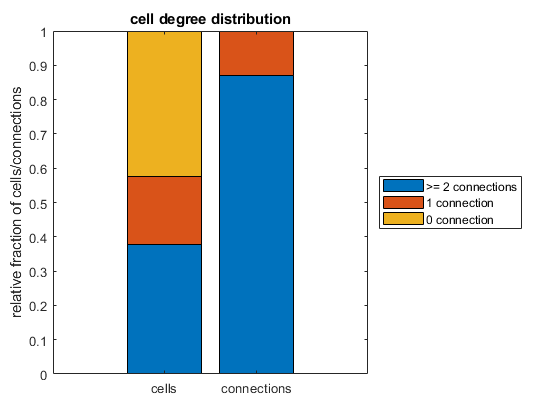


bar_data = [n_cell_2morecon n_cell_1con n_cell_nocon; n_con_2morecon n_con_1con n_con_nocon];
bar_data_percent = bar_data ./ sum(bar_data,2);
figure
bar([bar_data_percent],'stacked')
title('cell degree distribution')
xticklabels({'cells','connections'})
ylabel('relative fraction of cells/connections')
legend('>= 2 connections','1 connection','0 connection','Location','eastoutside')

## **Supplementary figure 1**

(A) Distance to slice surface

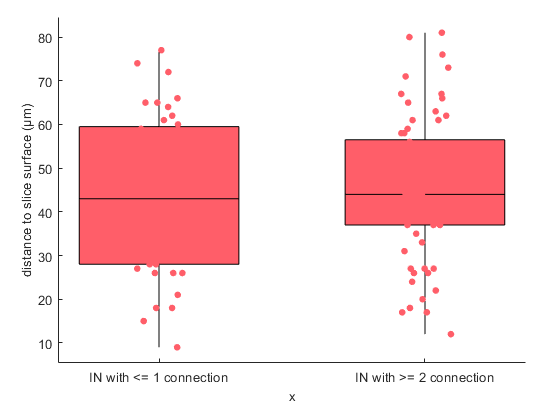

figure
g = gramm('x',tcell.con2more,'y',tcell.celldepthZ,'subset',filter_all);
g.stat_boxplot;
g.geom_jitter;
g.set_names('y','distance to slice surface (µm)');
g.axe_property('XTickLabel',{'IN with <= 1 connection','IN with >= 2 connection'},'XTick',[0:1]);
g.draw;

(B) Connection probability over z depth

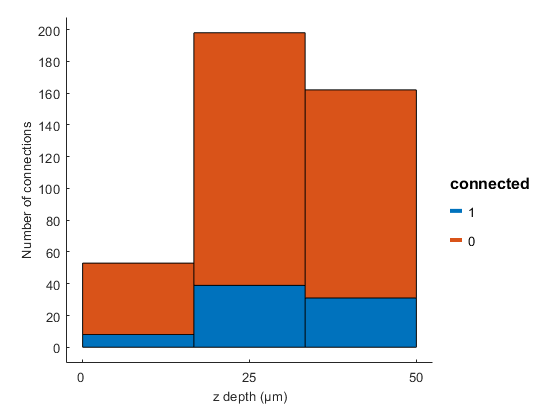

bins = [0 25 50 200];
dist_bin = discretize(tconnection.PreCell_celldepthZ,bins);

%IN-PC number of connections
figure
g = gramm('x',dist_bin,'color',tconnection.Connected,...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 3);
g.stat_bin('geom','stacked_bar','nbins',3);
g.set_color_options('map','matlab');
g.set_order_options('color',-1);
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.set_names('x','z depth (µm)','y','Number of connections','color','connected');
g.draw;

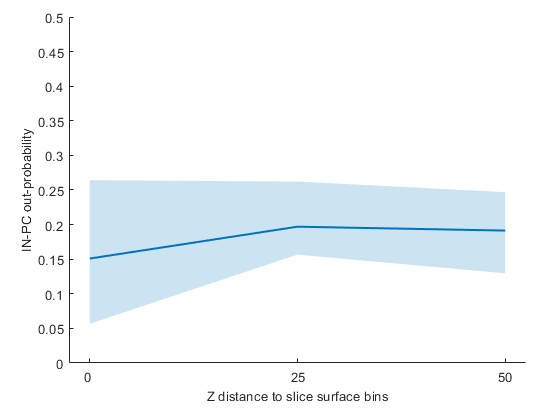


%IN-PC probability
figure
g = gramm('x',dist_bin,'y',tconnection.Connected',...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 3);
g.stat_summary('type','bootci');
g.axe_property('YLim',[0 0.5]);
g.set_names('x','Z distance to slice surface bins','y','IN-PC out-probability');
g.set_color_options('map','matlab');
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.draw();

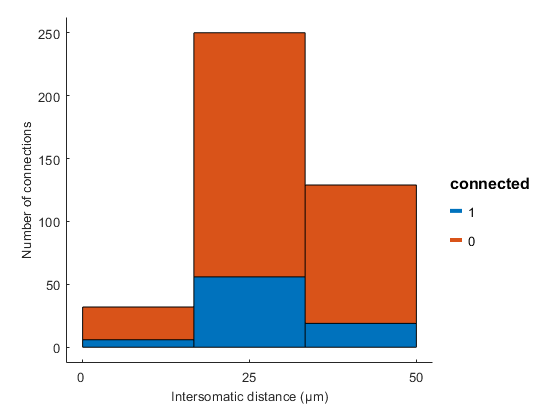


%PC-IN number of connections
figure
g = gramm('x',dist_bin,'color',tconnection.Connected,...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 2);
g.stat_bin('geom','stacked_bar','nbins',3);
g.set_color_options('map','matlab');
g.set_order_options('color',-1);
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.set_names('x','Intersomatic distance (µm)','y','Number of connections','color','connected');
g.draw;

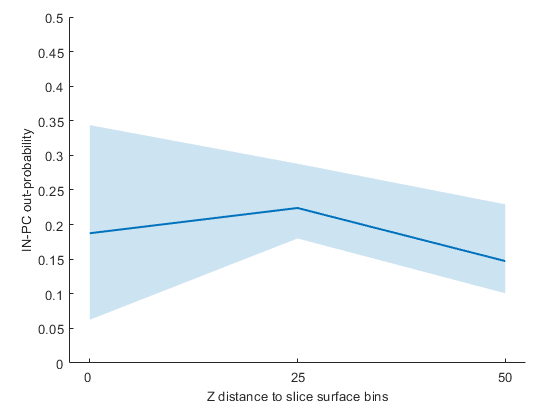


%PC-IN probability
figure
g = gramm('x',dist_bin,'y',tconnection.Connected',...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 2);
g.stat_summary('type','bootci');
g.axe_property('YLim',[0 0.5]);
g.set_names('x','Z distance to slice surface bins','y','IN-PC out-probability');
g.set_color_options('map','matlab');
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.draw();
hold off

(C) Distance-dependence of connectivity by IN with sparse or dense connectivity

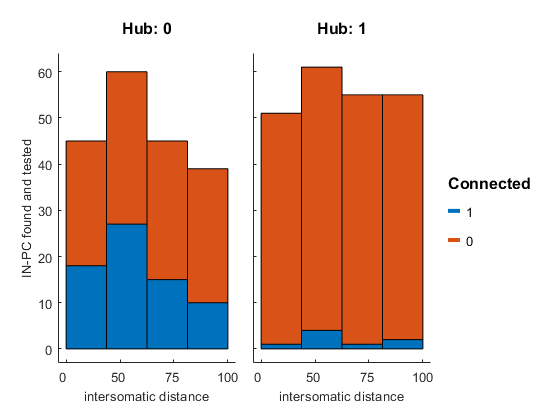

%label connections belonging to IN with x connection
for i = 1:size(tconnection,1)
    cellfilter = tcell.IDcell == tconnection.IDpre(i);
    tconnection.con2more_pre(i) = tcell.con2more(cellfilter);
    
    cellfilter = tcell.IDcell == tconnection.IDpost(i);
    tconnection.con2more_post(i) = tcell.con2more(cellfilter);
end

%IN n_con distance dependent connectivity
bins = [0 50 75 100 200];
dist_bin = discretize(tconnection.Distance,bins);

%found and tested IN-PC connections
figure
g = gramm('x',dist_bin,'color',tconnection.Connected,...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 3, ...
    'column',tconnection.con2more_pre);
g.stat_bin('geom','stacked_bar','nbins',4);
g.set_color_options('map','matlab');
g.set_order_options('color',-1);
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.set_names('x','intersomatic distance','y','IN-PC found and tested','column','Hub','color','Connected');
g.draw;

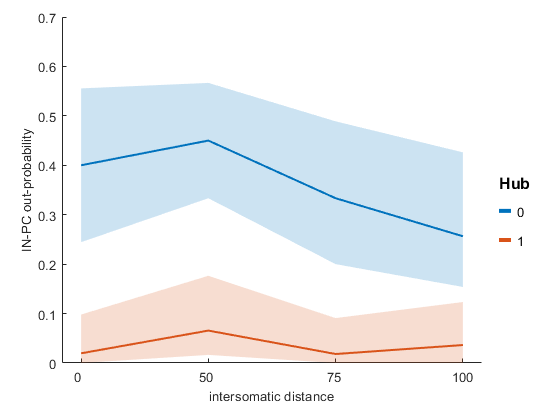


%IN-PC probability
figure
g = gramm('x',dist_bin,'y',tconnection.Connected',...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 3,...
    'color',tconnection.con2more_pre);
g.stat_summary('type','bootci');
g.axe_property('YLim',[0 0.7]);
g.set_names('x','intersomatic distance','y','IN-PC out-probability','color','Hub');
g.set_color_options('map','matlab');
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.draw();

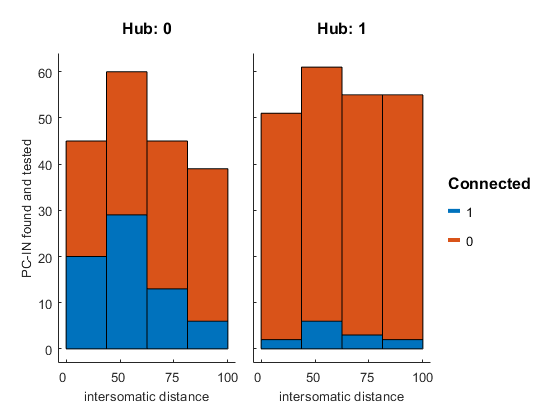


%found and tested PC-IN connections
figure
g = gramm('x',dist_bin,'color',tconnection.Connected,...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 2, ...
    'column',tconnection.con2more_post);
g.stat_bin('geom','stacked_bar','nbins',4);
g.set_color_options('map','matlab');
g.set_order_options('color',-1);
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.set_names('x','intersomatic distance','y','PC-IN found and tested','column','Hub','color','Connected');
g.draw;

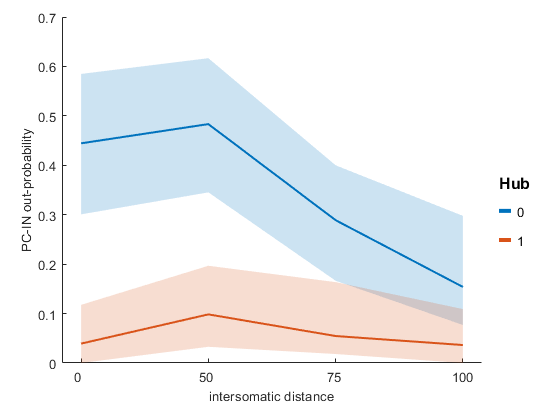


%PC-IN probability
figure
g = gramm('x',dist_bin,'y',tconnection.Connected',...
    'subset',tconnection.synaptic_layer == 0 & tconnection.stype == 2,...
    'color',tconnection.con2more_post);
g.stat_summary('type','bootci');
g.axe_property('YLim',[0 0.7]);
g.set_names('x','intersomatic distance','y','PC-IN out-probability','color','Hub');
g.set_color_options('map','matlab');
g.axe_property('XTickLabel',bins(1:end-1),'XTick',[1:length(bins)-1]);
g.draw();

(D) Hubinterneuron co-presence across slice

%filter tconnection of only relevant synapse type
confil = tconnection.stype == out_s & tconnection.synaptic_layer == layer;
tconnection2 = tconnection(confil,:);

%create tcluster
tcluster = table();
tcluster.id = categorical(unique(tconnection2.Idslice));
for i = 1:size(tcluster,1)
    cell_central_filter = tcell.Idslice == tcluster.id(i) & tcell.ctype == central_celltype & tcell.layer_sup_deep == layer;
    cell_partner_filter = tcell.Idslice == tcluster.id(i) & tcell.ctype == partner_celltype & tcell.layer_sup_deep == layer;
    tcluster.n_central(i) = sum(cell_central_filter);
    tcluster.n_partner(i) = sum(cell_partner_filter);
    tcluster.rec_found(i) = sum(tcell.out_recfound(cell_central_filter,out_s));
    tcluster.out_found(i) = sum(tcell.out_found(cell_central_filter,out_s));
    tcluster.in_found(i) = sum(tcell.in_found(cell_central_filter,in_s));
end

tcell.con2more = cell_type & cell_layer & (filter_nocon | filter_1con);
%include tcell.hub in tcluster
for i = 1:size(tcluster,1)
    cell_central_filter = tcell.Idslice == tcluster.id(i) & tcell.ctype == central_celltype & tcell.layer_sup_deep == layer;
    tcluster.con2more(i) = sum(tcell.con2more(cell_central_filter));
    tcluster.con1less(i) = sum(tcell.con2more(cell_central_filter) == 0);
end

fprintf('%d out of %d slices had 2 or more interneurons',sum(tcluster.n_central > 1),size(tcluster,1))

34 out of 61 slices had 2 or more interneurons

fprintf('out of these %d slices, %d had both hub and nonhub IN, %d had only hub, %d had only nonhub',...
    sum(tcluster.n_central > 1),sum(tcluster.con2more > 0 & tcluster.con1less > 0),...
    sum(tcluster.con2more > 0 & tcluster.con1less == 0), sum(tcluster.con2more == 0 & tcluster.con1less > 0));

out of these 34 slices, 23 had both hub and nonhub IN, 21 had only hub, 16 had only nonhub

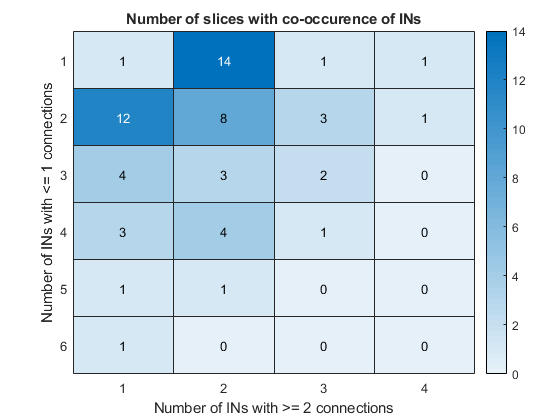


hub_matrix = crosstab(tcluster.con2more,tcluster.con1less);
figure
heatmap(hub_matrix)
xlabel('Number of INs with >= 2 connections')
ylabel('Number of INs with <= 1 connections')
title('Number of slices with co-occurence of INs')